# Copyright of this code belongs to Frank Lawless (flawless@uncc.edu).

Do not distribute this code.

clear all 
close all

% 'd' is the distance of the pen from the base of the robot
% 'k' is the control parameter
global d h k m delay;
d = 1.2; k = 10;
% d = .0469; k = .1;
h = .08; 

non_linear_control = true; m = 2;% Control II & switch threshold
delay = 2; % delay amount \delta


% noise magnitudes
angular_noise = .1;
linear_noise = .5;

%road trajectory and map
% position = importdata("int_traffic_circle.mat");

position = csvread("int_traffic_circle.csv");
down_sample_amount = 1; 
l = 1;
for i = 1:down_sample_amount:length(position)
    new_position(:,l) = position(:,i);
    l = l+1;
end

position = new_position;

state(:,1) =[position(1,1)-6; position(2,1)+d*2; 3*pi/2];

xb(1) = state(1,1) + d*cos(state(3,1));
yb(1) = state(2,1) + d*sin(state(3,1));

theta(1) = state(3,1); 
theta_hat(1) = state(3,1);

T = size(position,2)-1;
t = 1:T;

xVelocity = (position(1,t+1) - position(1,t))/h;
yVelocity = (position(2,t+1) - position(2,t))/h;
for i = 1:length(xVelocity)
    vr(i) = sqrt(xVelocity(i)^2+yVelocity(i)^2);
end
for t = 1 : T
    % x= current state
%     x = [xb(t); yb(t); theta(t)];
     x = [xb(t); yb(t); theta_hat(t)];
    
    % controller returns the desired velocities
    [v(t), w(t)] = controller(x, xVelocity(t), yVelocity(t),position(:,t));
    
    n1(t) = linear_noise-2*linear_noise*rand(1)*v(t);
    n2(t) = angular_noise-2*angular_noise*rand(1)*w(t);
    
    % use the dynamics with desired velocities to generate the velocities
    dot_x = dynamics(theta(t),v(t),w(t),n1(t),n2(t));
    
    linear_vel(t) = v(t)+n1(t);
    angular_vel(t) = w(t)+n1(t);    
     
    % centroid dynamics
    %actual
    
    % integrate the position to get the new position
    xb(t+1) = xb(t) + dot_x(1)*h;
    yb(t+1) = yb(t) + dot_x(2)*h;
    theta(t+1) = theta(t) + dot_x(3)*h;
    
%     state(:,t+1) = [xb(t+1); yb(t+1); theta(t+1)] - [d*cos(theta(t+1)); d*cos(theta(t+1)); 0];
    state(:,t+1) = state(:,t)+ [cos(theta(t)) 0; sin(theta(t)) 0; 0 1]*[linear_vel(t); angular_vel(t)]*h;

    if theta(t+1) > pi
        theta(t+1) = theta(t+1)-2*pi;
    elseif theta(t+1) < -pi
        theta(t+1) = theta(t+1)+2*pi;
    end 

    w_delay = [];
    if t >= 1+delay
        i=0;
    for l = t-delay:t
        i = i+1;
        w_delay(i) = w(l);
    end
            theta_hat(t+1) = atan2((state(2,t+1-delay)-state(2,t-delay))/(v(t-delay)), ...
            (state(1,t+1-delay)-state(1,t-delay))/(v(t-delay))) + sum(w_delay)*h;
    else
        i=0;
        for l = 1:t
        i = i+1;
        w_delay(i) = w(l);
        end
        theta_hat(t+1) = theta(1)+sum(w_delay)*h;
    end
end

% error 
for i = 1:length(position)
    error = [position(1,i) - xb(i); position(2,i) - yb(i)];
    error_norm(i) = norm(error);
    theta_e(i) = abs(theta(i)-theta_hat(i));
end
fprintf('Theta_e = %d', max(theta_e))

Theta_e = 6.516362e+00


test(1,:) = v;
test(2,:) = n1;
test(3,:) = v+n1;
test(4,:) = theta_e(1:end-1);

% velocity norm & noise
velocity_norm(1) = 0;
for i = 1:length(xb)-1
    Z = [xVelocity(i); yVelocity(i)];
    reference_velocity_norm(i) = norm(Z);
    u(i) = n1(i)^2+n2(i)^2*d^2;
end

% velocity bounds
for i = 1:length(xb)-1
    max_v(i) = max(reference_velocity_norm)+k*m;
    max_w(i) = 1/d*max(reference_velocity_norm)+k*m/d;
end

alpha = .5;
beta = .5;
gamma = (alpha^2+beta^2);
theta_max = delay*max(abs(n2));
eta = max(n1)^2+max(n2)^2*d^2

eta = 0.4541


c1 = 2*k*cos(theta_max)

c1 = 17.9760

c2 = 2*max(vr)^2/alpha^2*(sin(theta_max/2)^2)+eta/beta^2

c2 = 3.4731

c3 = m^2*c1-c2

c3 = 68.4311

c4 = c1-gamma;
error_norm(1)

ans = 6.1188

c3

c3 = 68.4311

m^2-c3/gamma

ans = -132.8621

error_norm(1)^2-c3/gamma

ans = -99.4221

tstar = 1/gamma*log((m^2-c3/gamma)/(error_norm(1)^2-c3/gamma))

tstar = 0.5799

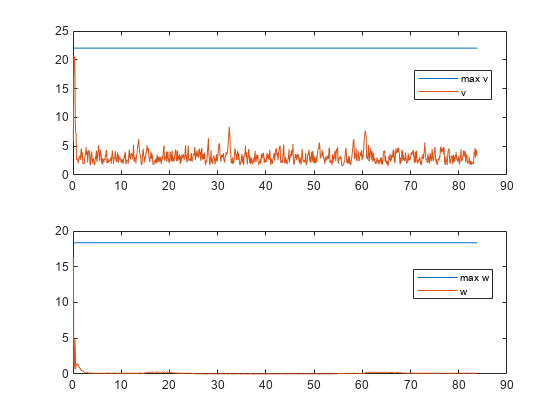

for t = 0:length(xb)-1
    i = t+1;
    if t*h <= tstar
          e_upper(i) = error_norm(1);
%         e_upper(i) = sqrt((error_norm(1)^2-c3/gamma)*exp(gamma*t*h)+c3/gamma);
    else
        e_upper(i) = sqrt((m^2-c2/c4)*exp(-c4*(t-tstar)*h)+c2/c4);
    end
end

%bounded velocities
figure
subplot(2,1,1)
plot([1:length(xb(1,:))-1]*h, max_v)
hold on
plot([1:length(xb(1,:))-1]*h, abs(v))
legend('max v','v','location','best')
hold off
subplot(2,1,2)
plot([1:length(xb(1,:))-1]*h, max_w)
hold on
plot([1:length(xb(1,:))-1]*h, abs(w))
legend('max w','w','location','best')
hold off

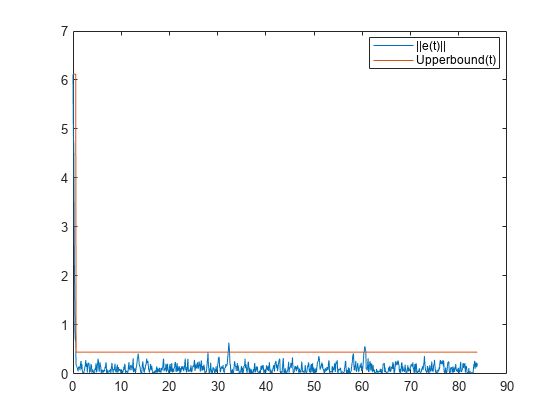


% bounded error
figure
plot([0:length(xb(1,:))-1]*h, error_norm)
hold on
plot([0:length(xb(1,:))-1]*h, e_upper)
legend('||e(t)||','Upperbound(t)','location','best')
hold off

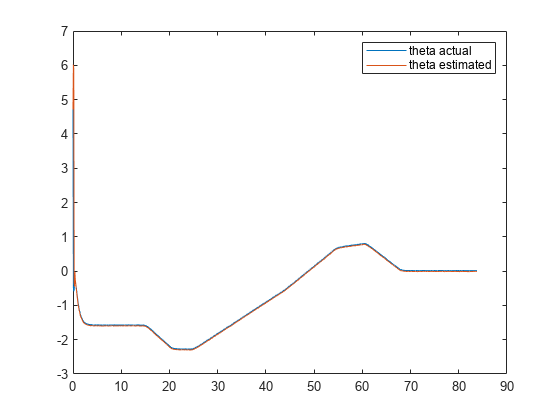


figure
plot([0:length(xb(1,:))-2]*h,theta(1:end-1))
hold on 
plot([0:length(xb(1,:))-2]*h,theta_hat(1:end-1))
legend('theta actual', 'theta estimated')
hold off

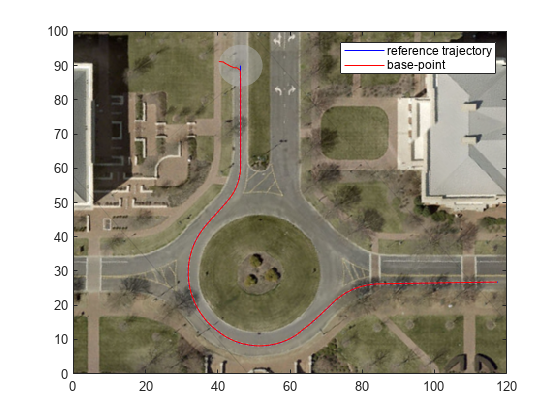


figure
map1 = imread('traffic circle map.png');
map = image(flip(map1,1),'XData',[0 120],'YData',[0 100]);
set(gca,'YDir','normal') 
hold on
for i = 1:10:length(xb)
    circle(position(1,i), position(2,i),e_upper(i),[.7 .7 .7],.5);
end

plot(position(1,:),position(2,:),'color','b');
plot(xb, yb,'color','r')
legend('reference trajectory','base-point', "location", 'northeast')
hold off

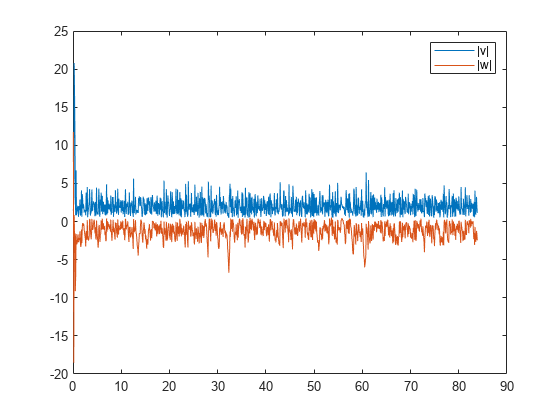

figure
plot([1:size(linear_vel,2)]*h, linear_vel); hold on
plot([1:size(angular_vel,2)]*h, angular_vel);
legend('|v|', '|w|')

function [v, w] = controller(x, xVelocity, yVelocity,position)
global d k m

J = [cos(x(3)) -d*sin(x(3));
    sin(x(3))  d*cos(x(3)) ];
E = x(1:2,1)- [position(1); position(2)];

if norm(E) > m 
        v_feedback = [xVelocity; yVelocity] - k*m/norm(E)*E;
    else
    v_feedback = [xVelocity; yVelocity] - k*E;
end

desired_control = (J)\v_feedback;

v = desired_control(1);
w = desired_control(2);

end

function dot_x = dynamics(theta,v,w,n1,n2)
global d

M = [cos(theta) -d*sin(theta);
     sin(theta)  d*cos(theta);
     0               1      ];

dot_x = M*[v+n1; w+n2];

end

function circles = circle(x,y,r,c,trans)
hold on
th = 0:pi/50:2*pi;
x_circle = r * cos(th) + x;
y_circle = r * sin(th) + y;
fill(x_circle, y_circle,c,'LineStyle','none','FaceAlpha', trans,'HandleVisibility','off')
end